copyright@ Xiaoxing Hu Email:72744505@qq.com 

modifide history: 2022/5/28

version:1.0

% input_test = [out.input1(:,2),out.input2(:,2),out.input3(:,2),out.input4(:,2)];
% output_test= [out.sensor1(:,2),out.seneor2(:,2),out.seneor3(:,2),out.seneor4(:,2)];
%-----------------------------------------------从仿真中读取数据
% input_train = normalize(input_train);
% input_test = normalize(input_test);
% output_train = normalize(output_train);
% output_test = normalize(output_test);
% normal_input = normalize(normal_input);
% normal_output = normalize(normal_output);
%-----------------------------------------------正规化数据

去除4、8传感器(有必要吗？

% normal_inputs = normal_input(1:2000,1:3);
% normal_outputs = normal_output(1:2000,1:3);
% normal_input_tests = normal_input_test(1:2000,1:3);
% normal_output_tests =normal_output_test(1:2000,1:3);
% fault1_inputs = fault1_input(1:2000,1:3);
% fault1_outputs = fault1_output(1:2000,1:3);
% fault1_input_tests = fault1_input_test(1:2000,1:3);
% fault1_output_tests = fault1_output_test(1:2000,1:3);
% fault2_inputs = fault2_input(1:2000,1:3);
% fault2_outputs = fault2_output(1:2000,1:3);
% fault2_input_tests = fault2_input_test(1:2000,1:3);
% fault2_output_tests = fault2_output_test(1:2000,1:3);
% fault3_inputs = fault3_input(1:2000,1:3);
% fault3_outputs = fault3_output(1:2000,1:3);
% fault3_input_tests = fault3_input_test(1:2000,1:3);
% fault3_output_tests = fault3_output_test(1:2000,1:3);
% fault4_inputs = fault4_input(1:2000,1:3);
% fault4_outputs = fault4_output(1:2000,1:3);
% fault4_input_tests = fault4_input_test(1:2000,1:3);
% fault4_output_tests = fault4_output_test(1:2000,1:3);

normal（normal和Fault的区别）

% Sig_Bank = [];
% [S,Omega_normal] = make_Omega(normal_input(1:1000,:)',normal_output(1:1000,:)');
% Sig_normal = Omega_normal * [normal_input(1:1000,:),normal_output(1:1000,:)]';
% Sig_normal = Sig_normal';
% Sig_fault1 = Omega_normal * [fault1_input(1:1000,:),fault1_output(1:1000,:)]';
% Sig_fault1 = Sig_fault1';
% Sig_fault2 = Omega_normal * [fault2_input(1:1000,:),fault2_output(1:1000,:)]';
% Sig_fault2 = Sig_fault2';
% Sig_fault3 = Omega_normal * [fault3_input(1:1000,:),fault3_output(1:1000,:)]';
% Sig_fault3 = Sig_fault3';
% Sig_fault4 = Omega_normal * [fault4_input(1:1000,:),fault4_output(1:1000,:)]';
% Sig_fault4 = Sig_fault4';
% 
% Sig_Bank = [Sig_normal, Sig_fault1, Sig_fault2, Sig_fault3, Sig_fault4]; %故障库,1000x20
% Sig_Bank = Sig_Bank';

fault_Omega

% Sig_Bank = [];
% [S0,Omega_normal] = make_Omega(normal_input(900:1000,:)',normal_output(900:1000,:)');
% % Sig_normal = Omega_normal * [normal_input(1:1000,:), normal_output(1:1000,:)]';
% [S1,Omega_fault1] = make_Omega(fault1_input(900:1000,:)',fault1_output(900:1000,:)');
% Sig_fault1 = Omega_fault1 * [fault1_input(900:1000,:), fault1_output(900:1000,:)]';
% [S2,Omega_fault2] = make_Omega(fault2_input(900:1000,:)',fault2_output(900:1000,:)');
% Sig_fault2 = Omega_fault2 * [fault2_input(900:1000,:), fault2_output(900:1000,:)]';
% [S3,Omega_fault3] = make_Omega(fault3_input(900:1000,:)',fault3_output(900:1000,:)');
% Sig_fault3 = Omega_fault3 * [fault3_input(900:1000,:), fault3_output(900:1000,:)]';
% [S4,Omega_fault4] = make_Omega(fault4_input(900:1000,:)',fault4_output(900:1000,:)');
% Sig_fault4 = Omega_fault4 * [fault4_input(900:1000,:), fault4_output(900:1000,:)]';
% % Sig_Bankk = [Sig_normal;Sig_fault1;Sig_fault2;Sig_fault3;Sig_fault4];
% Sig_Bankk = [Sig_fault1;Sig_fault2;Sig_fault3;Sig_fault4];
% % Sig_Bankk = Sig_Bankk;
% % size(Sig_Bankk)
% Sig_Bankk_withoutmean = Sig_Bankk - mean(Sig_Bankk,2); %去均值
% % mean(Sig_Bankk_withoutmean,2)
% % mean(Sig_Bankk_withoutmean,2)
% % Omega = [Omega_normal,Omega_fault1,Omega_fault2,Omega_fault3,Omega_fault4];
% Omega = [Omega_fault1, Omega_fault2, Omega_fault3, Omega_fault4];

测试数据

% % test_data = [fault4_input_tests(1:200,:),fault4_output_tests(1:200,:)]';
% % Sig_test = Omegakk5 * test_data;
% % Sig_test = Sig_test';
% % [rate, score] = get_score5(Sig_test, Sig_Bankk,5);
% % myplot(score,"真实错误是fault4")
% % Sig_Bankk = Sig_Bankk';
% % test_data = [normal_input(1001:1100,:),normal_output(1001:1100,:),fault1_input(1001:1100,:),fault1_output(1001:1100,:),fault2_input(1001:1100,:),fault2_output(1001:1100,:),fault3_input(1001:1100,:),fault3_output(1001:1100,:),fault4_input(1001:1100,:),fault4_output(1001:1100,:)];
% % Sig_Bankk_withoutmean1 = Sig_Bankk_withoutmean(1:100,:)-mean(Sig_Bankk_withoutmean(1:100,:));
% test_data = [fault1_input(1001:1100,:),fault1_output(1001:1100,:),fault2_input(1001:1100,:),fault2_output(1001:1100,:),fault3_input(1001:1100,:),fault3_output(1001:1100,:),fault4_input(1001:1100,:),fault4_output(1001:1100,:)];%不加normal数据
% % Sig_normal_test = Omega_normal * test_data(:,1:8)';
% % Sig_normal_test = Sig_normal_test';
% % Sig_fault1_test = Omega_normal * test_data(:,9:16)';
% % Sig_fault1_test = Sig_fault1_test';
% % Sig_fault2_test = Omega_normal * test_data(:,17:24)';
% % Sig_fault2_test = Sig_fault2_test';
% % Sig_fault3_test = Omega_normal * test_data(:,25:32)';
% % Sig_fault3_test = Sig_fault3_test';
% % Sig_fault4_test = Omega_normal * test_data(:,33:40)';
% % Sig_fault4_test = Sig_fault4_test'; 
% % test(Omega_normal,Sig_Bank,test_data)
% % test_2(Omega,Sig_Bankk_withoutmean,test_data) %fault Omega
% test_2(Omega,Sig_Bankk_withoutmean,test_data);%去均值
% % mean(Sig_Bankk_withoutmean)
% Sig_fault4_1 = Omega_fault1 * [fault4_input(1001:1100,:),fault4_output(1001:1100,:)]';
% Sig_fault4_1 = Sig_fault4_1';
% Sig_fault4_1 = Sig_fault4_1 - mean(Sig_fault4_1);
% Sig_fault4_2 = Omega_fault2 * [fault4_input(1001:1100,:),fault4_output(1001:1100,:)]';
% Sig_fault4_2 = Sig_fault4_2';
% Sig_fault4_2 = Sig_fault4_2 - mean(Sig_fault4_2);
% Sig_fault4_3 = Omega_fault3 * [fault4_input(1001:1100,:),fault4_output(1001:1100,:)]';
% Sig_fault4_3 = Sig_fault4_3';
% Sig_fault4_3 = Sig_fault4_3 - mean(Sig_fault4_3);
% Sig_fault4_test = Omega_fault4 * [fault4_input(1001:1100,:),fault4_output(1001:1100,:)]';
% Sig_fault4_test = Sig_fault4_test';
% Sig_fault4_test = Sig_fault4_test - mean(Sig_fault4_test);
% Sig_Bankk_withoutmean = Sig_Bankk_withoutmean';


随时间更新残差系数矩阵，基础版

% N = 100; %系数更新窗口大小是100
% score = [1 ,0.7, 0.4, 0.1];
% weight = [1,0.2,0.1,0.08];%权重系数
% rate = zeros(1,4);
% scorex = zeros(16,100);
% for i = 1:4 %4个故障 
%     for timeflag = 1001:1100
% %------------------------------------------------------
%         [S1,Omega_fault1] = make_Omega(fault1_input(timeflag-99:timeflag,:)',fault1_output(timeflag-99:timeflag,:)');
%         [S2,Omega_fault2] = make_Omega(fault2_input(timeflag-99:timeflag,:)',fault2_output(timeflag-99:timeflag,:)');
%         [S3,Omega_fault3] = make_Omega(fault3_input(timeflag-99:timeflag,:)',fault3_output(timeflag-99:timeflag,:)');
%         [S4,Omega_fault4] = make_Omega(fault4_input(timeflag-99:timeflag,:)',fault4_output(timeflag-99:timeflag,:)');
%         Omega = [Omega_fault1,Omega_fault2,Omega_fault3,Omega_fault4];%4x32
%         data = [fault1_input(timeflag,:),fault1_output(timeflag,:);fault2_input(timeflag,:),fault2_output(timeflag,:);fault3_input(timeflag,:),fault3_output(timeflag,:);fault4_input(timeflag,:),fault4_output(timeflag,:)];
% %------------------------------------------------------随时间更新Omega
%         sum = zeros(1,4);%计算残差的大小
%         vec = zeros(4,4);%行数表示残差的深度，列数表示Omega的种类
%          for j = 1:4 %4个Omega
%              vectemp = Omega(:,8*j-7:8*j) * data(i,:)';
%              vec(:,j) = vectemp;%4x4每一列代表一个Omega得到的残差
%          end
%          for k = 1:4
%              for l = 1:2%计算残差的个数
%                 sum(k) = sum(k) + weight(l)*abs(vec(l,k));
%              end
%          end
%             [sorted_sum,~] = sort(sum);
%             scorex(i*4-3,timeflag-1000) =  score(find(sorted_sum==sum(1)));
%             scorex(i*4-2,timeflag-1000) =  score(find(sorted_sum==sum(2)));
%             scorex(i*4-1,timeflag-1000) =  score(find(sorted_sum==sum(3)));
%             scorex(i*4,timeflag-1000) =  score(find(sorted_sum==sum(4)));
%     end
%     for m=1:N
%         if(scorex(5*i-4,m)==1)
%             rate(i)=rate(i)+1;
%         end
%     end
% end
% myplot(scorex,rate)

如果第一名一直没有换，那么我们有理由相信该第一名就是我们找的故障，为此我们增加记忆概率p, p随过去的第一名的记录次数而变化，例如，如果过去10次第一名都没有变化，第11次发生了变化，我们为了诊断的鲁棒性，不立刻切换它，而是以一定的概率P(10)切换它。

具体参数如下，算法开始，切换概率为1，任何故障成为第一名概率为1，不设障碍，如果下次第一名保持不变，切换概率-2%，切换概率最低为50%，同理，每次第一名（算出来的）更换一次，切换概率+5%

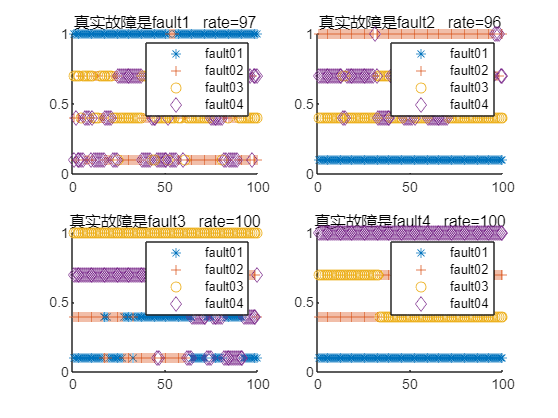

% N = 100; %系数更新窗口大小是100
% score = [1 ,0.7, 0.4, 0.1];
% weight = [1,0.2,0.1,0.08];%权重系数
% rate = zeros(1,4);
% scorex = zeros(16,100);
% p_flag = 0; %大于p_flag的可以切换，开始时切换概率为1.
% for i = 1:4 %4个故障 
%     for timeflag = 1001:1100
%         temp = zeros(1,4);%中间值
% %------------------------------------------------------
%         [S1,Omega_fault1] = make_Omega(fault1_input(timeflag-99:timeflag,:)',fault1_output(timeflag-99:timeflag,:)');
%         [S2,Omega_fault2] = make_Omega(fault2_input(timeflag-99:timeflag,:)',fault2_output(timeflag-99:timeflag,:)');
%         [S3,Omega_fault3] = make_Omega(fault3_input(timeflag-99:timeflag,:)',fault3_output(timeflag-99:timeflag,:)');
%         [S4,Omega_fault4] = make_Omega(fault4_input(timeflag-99:timeflag,:)',fault4_output(timeflag-99:timeflag,:)');
%         Omega = [Omega_fault1,Omega_fault2,Omega_fault3,Omega_fault4];%4x32
%         data = [fault1_input(timeflag,:),fault1_output(timeflag,:);fault2_input(timeflag,:),fault2_output(timeflag,:);fault3_input(timeflag,:),fault3_output(timeflag,:);fault4_input(timeflag,:),fault4_output(timeflag,:)];
% %------------------------------------------------------随时间更新Omega
%         sum = zeros(1,4);%计算残差的大小
%         vec = zeros(4,4);%行数表示残差的深度，列数表示Omega的种类
%          for j = 1:4 %4个Omega
%              vectemp = Omega(:,8*j-7:8*j) * data(i,:)';
%              vec(:,j) = vectemp;%4x4每一列代表一个Omega得到的残差
%          end
%          for k = 1:4
%              for l = 1:2%计算残差的个数
%                 sum(k) = sum(k) + weight(l)*abs(vec(l,k));
%              end
%          end
%             [sorted_sum,~] = sort(sum);
%             if timeflag ==1001
%                 scorex(i*4-3,timeflag-1000) =  score(find(sorted_sum==sum(1)));
%                 scorex(i*4-2,timeflag-1000) =  score(find(sorted_sum==sum(2)));
%                 scorex(i*4-1,timeflag-1000) =  score(find(sorted_sum==sum(3)));
%                 scorex(i*4,timeflag-1000) =  score(find(sorted_sum==sum(4)));
%             else
% %----------------------------------------------------------------------------
%                 last_score = [scorex(i*4-3,timeflag-1001),scorex(i*4-2,timeflag-1001),scorex(i*4-1,timeflag-1001),scorex(i*4,timeflag-1001)]; 
%                 flag_last = find(last_score==1);% find the index of No.1
%                 flag_temp = find(last_score==1);
%                 if(flag_last==flag_temp)
%                     p_flag = p_flag+0.02;
%                 else
%                     p_flag = p_flag-0.02;
%                 end
%                 if(p_flag<0)
%                     p_flag = 0;
%                 elseif(p_flag>0.7)
%                     p_flag = 0.7;% highest probability is 50%
%                 end
%                 test = rand;% generate a random number
%                 if(test>p_flag)
%                     scorex(i*4-3,timeflag-1000) =  score(find(sorted_sum==sum(1)));
%                     scorex(i*4-2,timeflag-1000) =  score(find(sorted_sum==sum(2)));
%                     scorex(i*4-1,timeflag-1000) =  score(find(sorted_sum==sum(3)));
%                     scorex(i*4,timeflag-1000) =  score(find(sorted_sum==sum(4)));
%                 else
%                     scorex(i*4-3,timeflag-1000) =  last_score(1);
%                     scorex(i*4-2,timeflag-1000) =  last_score(2);
%                     scorex(i*4-1,timeflag-1000) =  last_score(3);
%                     scorex(i*4,timeflag-1000) =  last_score(4);
%                 end
%             end
% %--------------------------------------------------------------------------增加惯性因子
%     end
%     for m=1:N
%         if(scorex(5*i-4,m)==1)
%             rate(i)=rate(i)+1;
%         end
%     end
% end
% myplot(scorex,rate)